# Teoría 8: Interpolación

## Polinomio interpolante

$f(x)=P_{n-1}(x)$    si y solo sí     $y=a_{n-1}x^{n-1}+\cdots+a_{1}x+a_0$

Hay $n$** incognitas** (coeficientes)

- Se necesitan $n$** datos** $(x_i,y_i)$: $(x_0,y_0),(x_1,y_1),\dots,(x_{n-1},y_{n-1})$

### Error de interpolación

**Definición:** error (función)

                            
$$E_n(x,f) = f(x) - P_n(x)$$


format short
% Datos de ejemplo
xi = [0 0.6 0.9]'

xi =          0
    0.6000
    0.9000


yi = cos(xi) % f(x) = cos(x)

yi =     1.0000
    0.8253
    0.6216



% Polinomio de Newton
p_newton = polynewton(xi, yi);

% Para evaluar
xq = 0:0.05:0.9;
yq_newton = polyval(p_newton, xq);  % y aproximados
yq_exacto = cos(xq);                % y exacto

% Graficar los datos y los polinomios de interpolación
figure;
plot(xi, zeros(3,1), 'o', 'MarkerFaceColor', 'b');

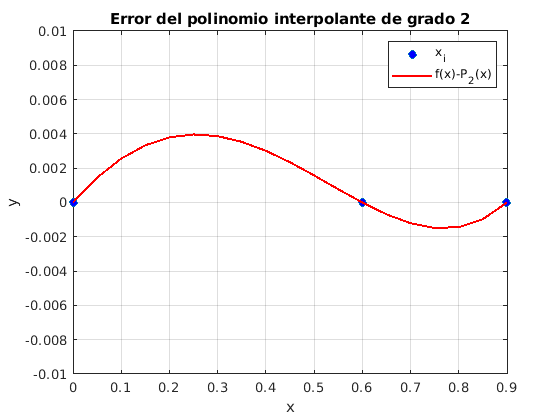

hold on;
plot(xq, yq_exacto - yq_newton, 'r-', 'LineWidth', 1.5);
ylim([-1e-2 1e-2])
xlabel('x');
ylabel('y');
title('Error del polinomio interpolante de grado 2');
legend('x_i', 'f(x)-P_2(x)',"Location","northeast");
grid on;
hold off;

**Estimación analítica **

Por fórmula de Taylor

                            
$$E_n(x,f) = \frac{f^{(n+1)}(\xi(x))}{(n+1)!}(x-x_0)\ldots(x-x_n)$$


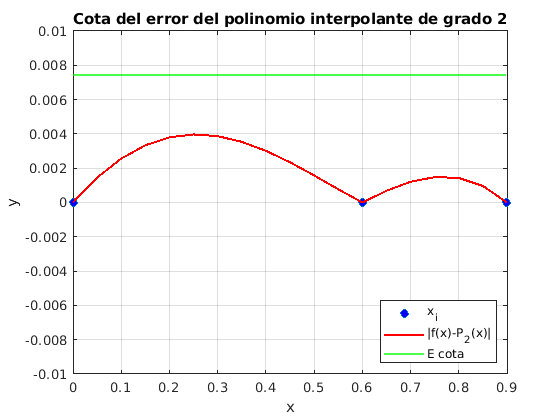

% Máximo de la tercera derivada de f
f=@(x) cos(x);
syms t
f_xxx = matlabFunction(diff(f(t),t,3));
xi_max = 0.9;

% Máximo de g
g=@(x) (x-xi(1)) .* (x-xi(2)) .* (x-xi(3));
syms t
x_crit = solve(diff(g(t),t) == 0);
x_max = double(x_crit(1));

% Cota
E_cota = abs( f_xxx(xi_max) * g(x_max) ) / factorial(3);

% Graficar los datos y los polinomios de interpolación
figure;
plot(xi, zeros(3,1), 'o', 'MarkerFaceColor', 'b');
hold on;
plot(xq, abs(yq_exacto - yq_newton), 'r-', 'LineWidth', 1.5);
yline(E_cota,'g-', 'LineWidth', 1.5)
ylim([-1e-2 1e-2])
xlabel('x');
ylabel('y');
title('Cota del error del polinomio interpolante de grado 2');
legend('x_i', '|f(x)-P_2(x)|','E cota',"Location","southeast");
grid on;
hold off;

**Estimación numérica**

Regla del término siguiente: para $y=f(x)$

                                
$$E_n(x,f) \approx y[x_0,\ldots,x_n,x_{n+1}](x-x_0)\ldots(x-x_n)$$


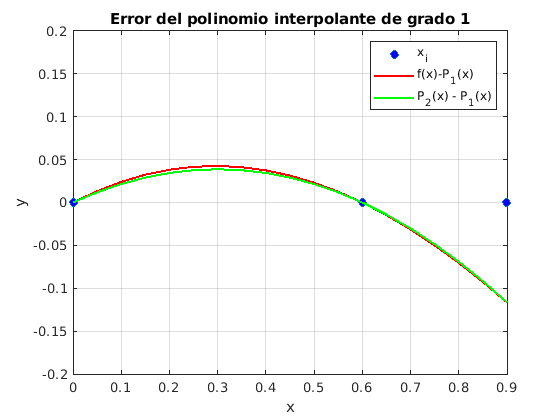

% Datos de ejemplo
xi = [0 0.6 0.9]';
yi = cos(xi);

% Polinomio de grado 1
P1 = polyfit(xi(1:end-1),yi(1:end-1),1); 

% Regla del término siguiente
M = tabladif(xi, yi); % Tabla de diferencias divididas
E1 = @(x) M(1,end) .* prod(x-xi(1:end-1)); % Función error de P1

% Para evaluar
xq = 0:0.05:0.9;
yq_newton = polyval(P1, xq);
yq_exacto = cos(xq);
E1_exacto = yq_exacto - yq_newton;
E1_aprox = E1(xq);

% Graficar los datos y los polinomios de interpolación
figure;
plot(xi, zeros(3,1), 'o', 'MarkerFaceColor', 'b');
hold on;
plot(xq, E1_exacto, 'r-', 'LineWidth', 1.5);
plot(xq, E1_aprox, 'g-', 'LineWidth', 1.5);
ylim([-0.2 0.2])
xlabel('x');
ylabel('y');
title('Error del polinomio interpolante de grado 1');
legend('x_i', 'f(x)-P_1(x)','P_2(x) - P_1(x)',"Location","northeast");
grid on;
hold off;

Ejercicio: Graficar el polinomio interpolante de grado 1 versus el modelo exacto

## Spline cúbico

Para los datos 

                
$$(x_0,y_0),(x_1,y_1),(x_2,y_2)$$


Ahora el modelo $f(x)$ es un conjunto de polinomios cúbico 

            
$$\left\{ 
\begin{array}{cc}
S_0(x)=a_0x^3+b_0x^2+c_0 x+d_0 & x_0 \le x \le x_1 \\
S_1(x)=a_1x^3+b_1x^2+c_1 x+d_1 & x_1 \le x \le x_2 
\end{array}
\right.$$


clear x a b c
syms x a b c

disp('Polinomios del Spline:')

Polinomios del Spline:


S0=-x^3

$$S0 = -x^{3}$$

S1=0.5*(x - 1)^3 + a*(x - 1)^2 + b*(x - 1) + c

$$S1 = c+\frac{{\left(x-1\right)}^{3}}{2}+b\,\left(x-1\right)+a\,{\left(x-1\right)}^{2}$$


disp('Derivadas:')

Derivadas:


dS0=diff(S0,x)

$$dS0 = -3\,x^{2}$$

d2S0=diff(S0,x,2)

$$d2S0 = -6\,x$$

dS1=diff(S1,x)

$$dS1 = b+\frac{3\,{\left(x-1\right)}^{2}}{2}+a\,\left(2\,x-2\right)$$

d2S1=diff(S1,x,2)

$$d2S1 = 2\,a+3\,x-3$$


disp('Condición de naturalidad:')

Condición de naturalidad:


subs(d2S0,x,0) == 0

$$ans = 0=0$$

subs(d2S1,x,3) == 0

$$ans = 2\,a+6=0$$

solve(subs(d2S1,x,3) == 0)

$$ans = -3$$


disp('Condición de continuidad:')

Condición de continuidad:


subs(S0,x,1) == subs(S1,x,1)

$$ans = -1=c$$

subs(dS0,x,1) == subs(dS1,x,1)

$$ans = -3=b$$

subs(d2S0,x,1) == subs(d2S1,x,1)

$$ans = -6=2\,a$$


% Por lo tanto
a=-3; b=-3; c=-1;

No se consideró la *Condición de interpolación*: $S_0(x_0)=y_0, ~S_1(x_1)=y_1,~S_1(x_2)=y_2$

### Algoritmo

Manual

    
$$\left\{ 
\begin{array}{cc}
S_0(x)=a_0(x-x_0)^3+b_0(x-x_0)^2+c_0 (x-x_0)+d_0 & x_0 \le x \le x_1 \\
S_1(x)=a_1(x-x_1)^3+b_1(x-x_1)^2+c_1 (x-x_1)+d_1 & x_1 \le x \le x_2 
\end{array}
\right.$$


% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]'; 

% Número de intervalos = número de polinomios
N = length(xi) - 1 

N = 3

% Variaciones en los xi = diferencias de los xi
H = diff(xi) 

H =      3
     1
     3


% Pendientes de los intervalos = diferencias divididas de primer orden
E = diff(yi) ./ H 

E =     -1
     4
     1



% Matriz de coeficientes de las segundas derivadas
diagprinc = 2 * (H(1:N-1) + H(2:N)); 
diagsupinf = H(2:N-1);
A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1)

A =      8     1
     1     8



% Lado derecho = variaciones en las diferencias divididas de y
b = 6 * diff(E)

b =     30
   -18



% Resolver el sistema lineal para encontrar las segundas derivadas
format rational
M = A \ b

M =       86/21    
     -58/21    


    
% Añadir condiciones de frontera naturales
M = [0; M; 0] 

M =        0       
      86/21    
     -58/21    
       0       



% Coeficientes de los polinomios
S = NaN(N,4);
for i = 1:N
    S(i, 4) = yi(i);
    S(i, 3) = E(i) - (M(i+1) + 2 * M(i)) * H(i) / 6;
    S(i, 2) = M(i) / 2;
    S(i, 1) = (M(i+1) - M(i)) / (6 * H(i));
end
format rational
S

S =       43/189          0            -64/21           5       
      -8/7           43/21          65/21           2       
      29/189        -29/21          79/21           6       


format short

Implementación

% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]'; 

% Spline Cúbico Natural
S = splinenatural(xi, yi);

% Para evaluar
%xq = [0:1:7]';
xq = 1.5

xq = 1.5000

[S, yq_spline] = splinenatural(xi, yi, xq)

S =     0.2275         0   -3.0476    5.0000
   -1.1429    2.0476    3.0952    2.0000
    0.1534   -1.3810    3.7619    6.0000


yq_spline = 1.1964

### Comparación gráfica

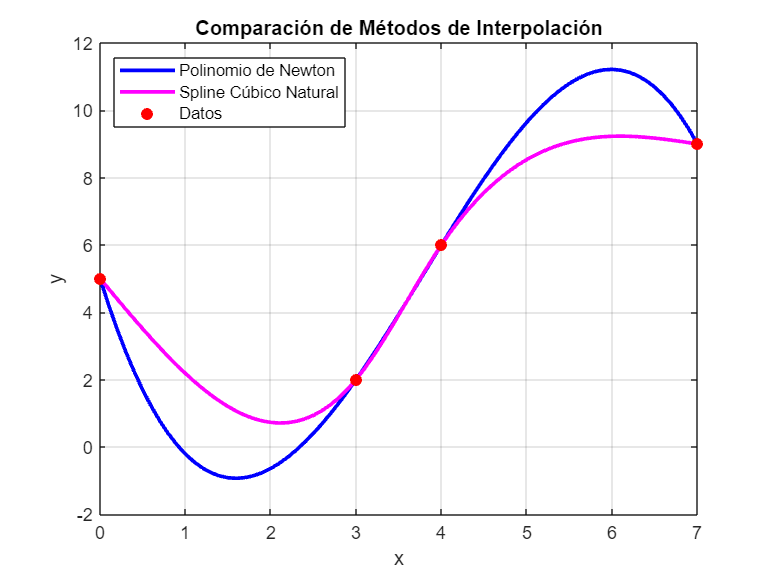

% Datos de ejemplo
xi = [0 3 4 7]';
yi = [5 2 6 9]'; 

% Para evaluar
xq = [0:0.1:7]';
[~,yq_spline] = splinenatural(xi, yi,xq);

% Evaluar los polinomios en un conjunto de puntos
p_newton = polynewton(xi,yi);
yq_newton = polyval(p_newton, xq);

% Graficar los datos y los polinomios de interpolación
figure;
plot(xq, yq_newton, 'b-', 'LineWidth', 2);
hold on;
plot(xq, yq_spline, 'm-', 'LineWidth', 2);
plot(xi, yi, 'ro', 'MarkerFaceColor', 'r');
xlabel('x');
ylabel('y');
title('Comparación de Métodos de Interpolación');
legend('Polinomio de Newton', 'Spline Cúbico Natural', 'Datos',...
    "Location","northwest");
grid on;
hold off;

function M = tabladif(x, y)
    %   M = TABLADIF(x, y) devuelve la tabla de diferencias divididas de Newton
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       M - Matriz donde la primera columna es x y las siguientes columnas
    %           contienen las diferencias divididas.

    n = length(x);      % Número de puntos
    M = zeros(n);       % Inicializar la matriz M
    M(1:n, 1) = y;      % Primera columna de M es y

    % Calcular las diferencias divididas
    for k = 1:n-1
        dx = x(k+1:n) - x(1:n-k); % Diferencias de x
        dy = diff(y) ./ dx;       % Diferencias divididas
        M(1:n-k, k+1) = dy;       % Llenar la columna k+1 de M
        y = dy;                   % Actualizar y para el siguiente paso
    end

    M = [x(:) M]; % Añadir la columna x al principio de la matriz M
end

function p = polynewton(x, y)
    %   p = POLYNEWTON(x, y) devuelve los coeficientes del polinomio de interpolación
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       p - Vector de coeficientes del polinomio de interpolación de Newton.

    M = tabladif(x, y); % Obtener la tabla de diferencias divididas
    n = length(x);      % Número de puntos
    b = M(1, 2:end);    % Coeficientes del polinomio de Newton
    p = b(1);           % Inicializar el polinomio con el primer coeficiente

    % Construir el polinomio de Newton
    for k = 2:n
        % Actualizar el polinomio con el siguiente término
        p = [0 p] + b(k) * poly(x(1:k-1)); 
    end
end

function [S, yq] = splinenatural(X, Y, xq, draw)
    % SPLINENATURAL Interpolación usando splines cúbicos naturales.
    %   [S, yq] = splinenatural(X, Y, xq, draw) devuelve los coeficientes de los
    %   polinomios cúbicos y los valores interpolados en los puntos de consulta.
    %
    %   Entrada:
    %       X    - Vector fila de puntos de datos.
    %       Y    - Vector fila de valores de la función en los puntos X.
    %       xq   - Vector fila de puntos a evaluar en la interpolación.
    %       draw - Lógico (0 o 1), indica si se grafica la interpolación (opcional).
    %
    %   Salida:
    %       S  - Matriz de coeficientes de los polinomios cúbicos (cada fila es un polinomio).
    %       yq - Vector fila de valores interpolados en los puntos xq.

    if nargin < 4
        draw = 0; % Por defecto no se grafica
        if nargin < 3
            xq = NaN; % Si no se proporcionan puntos de consulta, se establece como NaN
        end
    end
    
    X = X(:); % Convertir X como arreglo fila
    Y = Y(:); % Convertir Y como arreglo fila
    N = length(X) - 1; % Número de intervalos
    H = diff(X); % Diferencias entre puntos X
    E = diff(Y) ./ H; % Pendientes de los intervalos

    % Matriz de coeficientes de las segundas derivadas
    diagprinc = 2 * (H(1:N-1) + H(2:N)); 
    diagsupinf = H(2:N-1);
    A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1);

    % Vector de términos independientes
    b = 6 * diff(E);

    % Resolver el sistema lineal para encontrar las segundas derivadas
    g = A \ b; 
    g = [0; g; 0]; % Añadir condiciones de frontera naturales

    % Inicializar la salida yq
    yq = NaN(size(xq));
    S = zeros(N, 4); % Inicializar matriz de coeficientes

    % Calcular los coeficientes de los polinomios cúbicos
    for i = 1:N
        S(i, 1) = (g(i+1) - g(i)) / (6 * H(i));
        S(i, 2) = g(i) / 2;
        S(i, 3) = E(i) - H(i) * (g(i+1) + 2 * g(i)) / 6;
        S(i, 4) = Y(i);

        % Evaluar los polinomios en los puntos de consulta
        indx = find(xq >= X(i) & xq <= X(i+1)); 
        yq(indx) = S(i, 1) * (xq(indx) - X(i)).^3 + S(i, 2) * (xq(indx) - X(i)).^2 + S(i, 3) * (xq(indx) - X(i)) + S(i, 4);

        % Graficar si se solicita
        if draw == 1
            xx = linspace(X(i), X(i+1), 100);
            yy = S(i, 1) * (xx - X(i)).^3 + S(i, 2) * (xx - X(i)).^2 + S(i, 3) * (xx - X(i)) + S(i, 4);
            plot(xx, yy) 
            hold on
        end
    end

    % Configuración de la gráfica
    if draw == 1
        grid on 
        hold off
    end
end